# TEHTÄVÄ 2


format long g
load carsmall
clear t.Value
clear percent
tbl = tabulate(Origin);
t = cell2table(tbl,'VariableNames', ...
 {'Value','Count','Percent'})

t = 6×3 table
       Value       Count    Percent
    ___________    _____    _______

    {'USA'    }     69        69   
    {'France' }      4         4   
    {'Japan'  }     15        15   
    {'Germany'}      9         9   
    {'Sweden' }      2         2   
    {'Italy'  }      1         1   


t = sortrows(t,2,"descend");
Countries = categorical(t.Value);
%turning Countries into Categories for
%Graph
Amount = t.Count;
%Saving the car amount into a Variable
newTable = table(Countries,Amount)

newTable = 6×2 table
    Countries    Amount
    _________    ______

     USA           69  
     Japan         15  
     Germany        9  
     France         4  
     Sweden         2  
     Italy          1  


%Checking for validity
bar(Amount);
set(gca,'xticklabel',Countries);
%set manages graphical interface 
%only way to properly allocate x axis with
%the correct names
%Categorical value setting doesn't work
%with sort function.
mode(Amount , 'all')

ans =      1


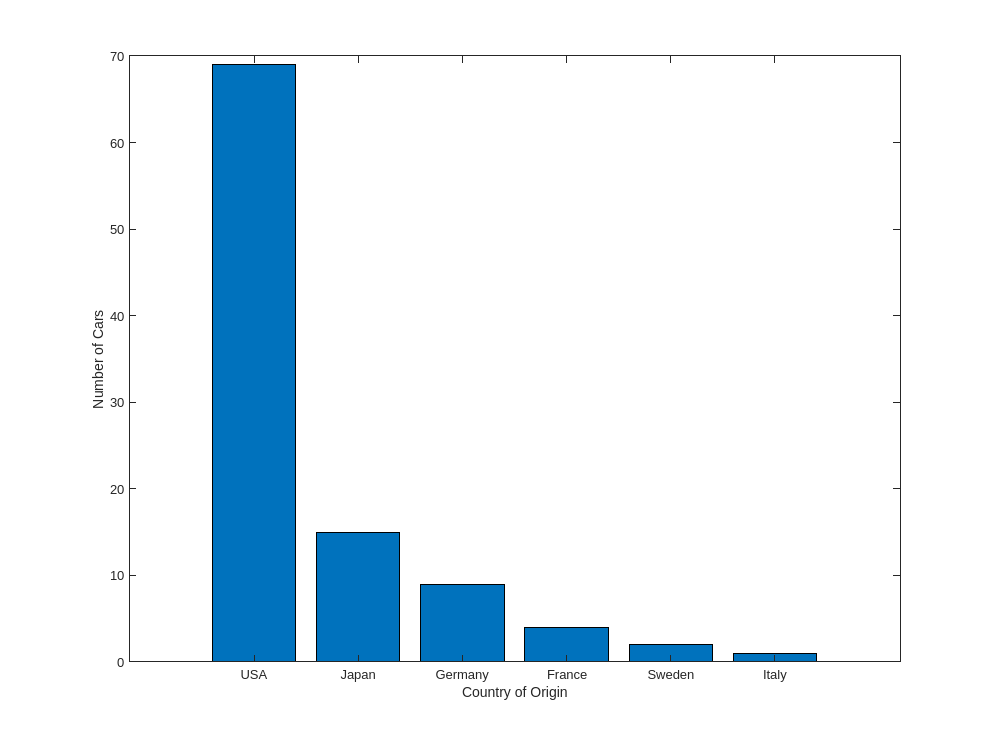


xlabel('Country of Origin')
ylabel('Number of Cars')

hold off



tbl = tabulate(Cylinders);
t = array2table(tbl,"VariableNames", ...
    {'Cylinders','Count','Percent'})

t = 8×3 table
    Cylinders    Count    Percent
    _________    _____    _______

        1          0         0   
        2          0         0   
        3          0         0   
        4         51        51   
        5          0         0   
        6         17        17   
        7          0         0   
        8         32        32   


mode(t.Percent,"all")

ans =      0


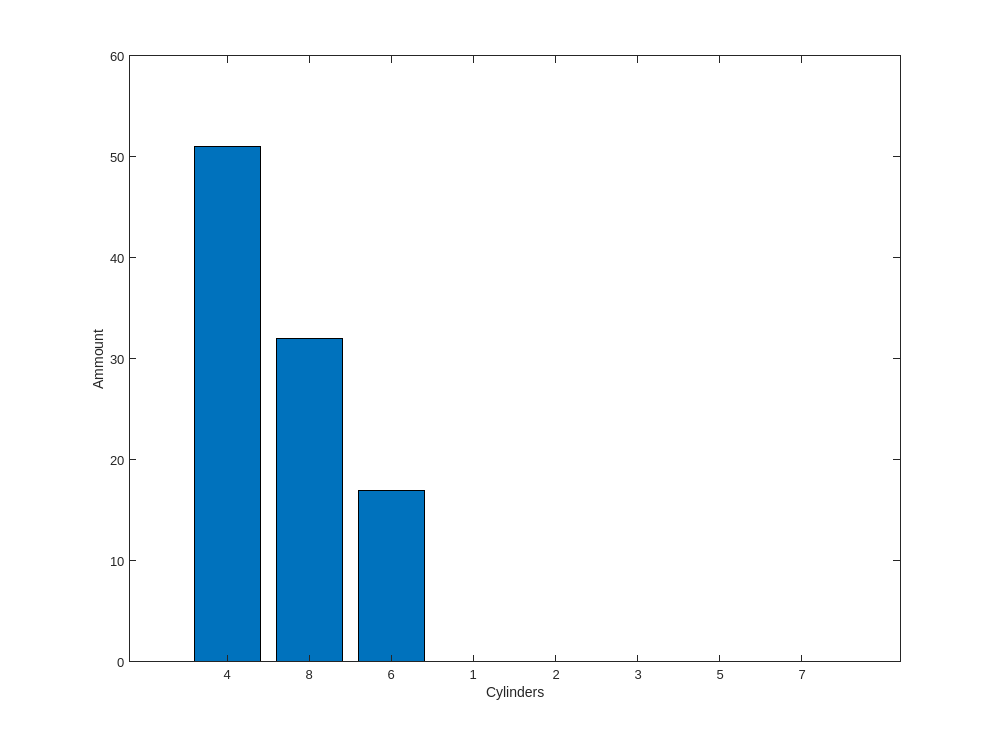

t = sortrows(t,2,"descend");
%sorting tables according to the amount
Cylinders = categorical(t.Cylinders);
%turning cylinders into categories.

bar(t.Count)
set(gca,'xticklabel',Cylinders);

xlabel("Cylinders")
ylabel("Ammount")

## TEHTÄVÄ 3 


load carsmall.mat
clear carAccs
Model_Year

Model_Year =     70
    70
    70
    70
    70
    70
    70
    70
    70
    70


clear carYear
carAccs70 = Acceleration(1:35,1)

carAccs70 =                         12
                      11.5
                        11
                        12
                      10.5
                        10
                         9
                       8.5
                        10
                       8.5


carAccs76 = Acceleration(35:69,1)

carAccs76 =                       18.5
                      15.5
                      16.9
                      14.9
                      17.7
                      15.3
                        13
                        13
                      13.9
                      12.8


carAccs82 = Acceleration(70:100,1)

carAccs82 =                       19.6
                      18.6
                        18
                      16.2
                        16
                        18
                      16.4
                      20.5
                      15.3
                      18.2


carYear82 = Model_Year(70:100,1);
carAccs82 = sortrows(carAccs82,1,"descend")

carAccs82 =                       24.6
                      20.5
                      19.6
                      19.4
                      18.6
                      18.6
                      18.2
                        18
                        18
                      17.6


tableNames = ["Year model", "Acceleration"]

tableNames = 1×2 string array
    "Year model"    "Acceleration"


% accessing the needed data

carAccs = Acceleration

carAccs =                         12
                      11.5
                        11
                        12
                      10.5
                        10
                         9
                       8.5
                        10
                       8.5


carYear = Model_Year;
carYear82 = categorical(carYear82)

carYear82 = 31×1 categorical array
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 
     82 



x = table(carYear,carAccs,VariableNames = tableNames)

x = 100×2 table
    Year model    Acceleration
    __________    ____________

        70              12    
        70            11.5    
        70              11    
        70              12    
        70            10.5    
        70              10    
        70               9    
        70             8.5    
        70              10    
        70             8.5    
        70            17.5    
        70            11.5    
        70              11    
        70            10.5    
        70              11    
        70              10    


x = sortrows(x,2,"descend")

x = 100×2 table
    Year model    Acceleration
    __________    ____________

        82            24.6    
        76            22.2    
        76            22.1    
        76            21.9    
        76              21    
        70            20.5    
        82            20.5    
        82            19.6    
        82            19.4    
        82            18.6    
        82            18.6    
        70            18.5    
        82            18.2    
        82              18    
        82              18    
        76            17.8    


carAccs = sortrows(carAccs,1,"descend")

carAccs =                       24.6
                      22.2
                      22.1
                      21.9
                        21
                      20.5
                      20.5
                      19.6
                      19.4
                      18.6


bar(carAccs)
mode(carAccs82);
median(carAccs82);
mean(carAccs82);
skewness(carAccs82);
xlabel("Cars")
ylabel("Acceleration")




med = median(carAccs)

med =                      15.15


men = mean(carAccs)

men =                     15.028


mod = mode(carAccs)

mod =                       14.5


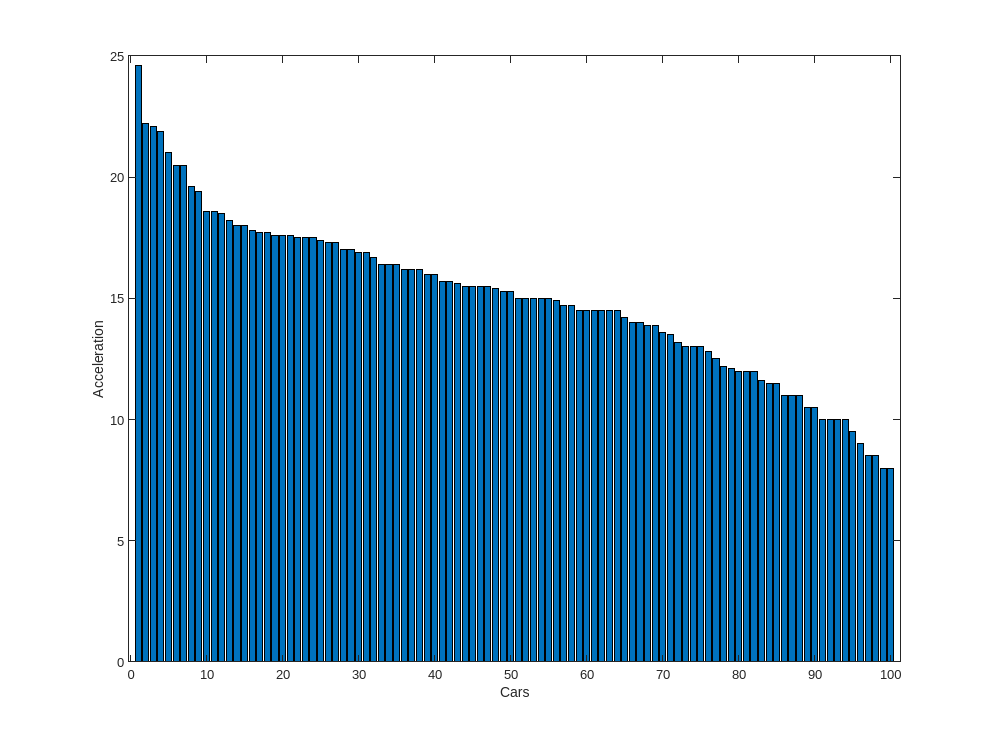

hold off

m = [1;1;1]

m =      1
     1
     1


m(1,1) = med;
m(2,1) = men;
m(3,1) = mod;
m = sortrows(m,1)

m =                       14.5
                    15.028
                     15.15


M = table(m,'RowNames',{'Median','Mean','Mode'}, ...
    'VariableNames',{'Values'})

M = 3×1 table
              Values
              ______

    Median      14.5
    Mean      15.028
    Mode       15.15


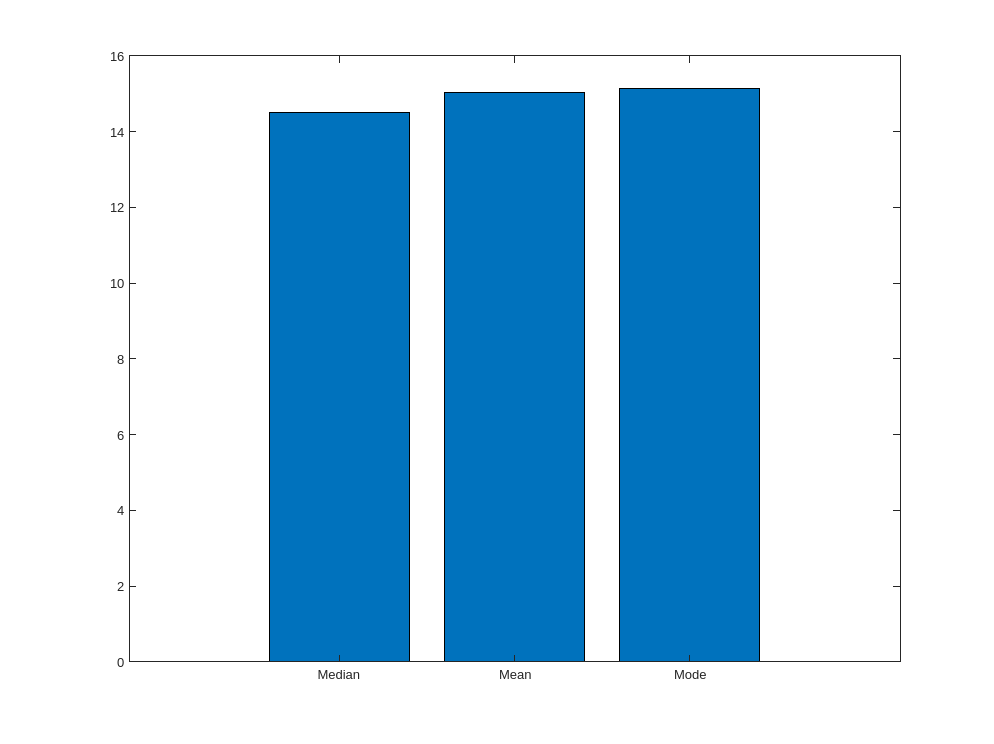


bar(m)
set(gca,'xticklabel',M.Properties.RowNames)

## TEHTÄVÄ 4


std(m)

ans =          0.345487095755157


var(m)

ans =          0.119361333333333


## TEHTÄVÄ 5

TuloJakauma=[3500 5500; 0.75 0.25]  

TuloJakauma =                       3500                      5500
                      0.75                      0.25



TuloTaulukko = table(TuloJakauma,'RowNames',{'Eurot','Prosentit'}, ...
    'VariableNames',{'Tuloero'})

TuloTaulukko = 2×1 table
                   Tuloero   
                 ____________

    Eurot        3500    5500
    Prosentit    0.75    0.25


s = 75;
a = 25;

m = ones(75,1) * 3500;
b = ones(25,1) * 5500;
newMat = cat(1,m,b);
mean(newMat)

ans =         4000


median(newMat)

ans =         3500



% keskiarvo on eli mean 5500 ja todellinen arvo on 3500 
%niin suurin osa työntekijöistä siis tienaa noin 3500 luokkaa
% ja jos työntekijöitä on 100 niin 75 niistä tienaa
% todennäköisesti 3000 ja 4000 välillä
%ääripää jota otetaan huomioon medianissa on 25% työntekijöistä
%jotka tienaa helposti yli 5000
% Median on siis alhaisempi kun keskiarvo jos nähdään
%luvun alkavan 75% työntekijöiden puolesta 3500
%ja 25% 5500 palkalla
%todellisuudessa voi olettaa keskimäärin alhaisempaa
% palkkaa kun mitä keskiarvo saattaa ilmoittaa
%eli palkka on noin alle 3500 luokkaa todellisuudessa


## TEHTÄVÄ 6

frequence = [1 30;2 40;3 30];
frequenceb = [3 30;4 40;5 30;];
%miks tätä kysytään kun arvot on identisiä
std(frequence);
std(frequenceb);


frequencea =[3, 10;4, 40;5, 40;6, 10];
frequenceA = [1, 40;2, 10;3, 10;4, 40];
std(frequencea);
std(frequenceA);
frequencec=[1 10;2 20;3 30;4 20;5 10];
std(frequencec);
frequenceC=[1 5;2 25;3 40;4 25;5 5];
std(frequenceC);
frequenced=[1 5;2 5;3 20;4 40;5 20;6 5;7 5];
std(frequenced);
frequenceD=[3 10;4 20;5 40;6 20;7 10];
std(frequenceD);


## TEHTÄVÄ 7

%MATLAB does not provide a way to define a reference to a value, as in languages like C++. Instead, MATLAB allows multiple output as well as multiple input parameters so that you know what values are going into a function and what values are coming out of the function.
%eli käytännössä matlabi ei säilytä dataa 
%muitten ohjelmointikielien tapaan joten
% datan säilyttäminen on erilaista
%tämän takia kopioiden tekemeinen referenssien perus
%teella on mahdotonta tehdä verrattuna esimerkiksi
% C++ tapaiseen ohjelmointiin
TuloJakauma

TuloJakauma =                       3500                      5500
                      0.75                      0.25


cov(TuloJakauma)

ans =              6122375.28125             9622500.09375
             9622500.09375            15123625.03125


corr(newMat

ans =      1
